## `PS3`

`刘沛雨 2100012289 信息科学技术学院`

`本次作业内容`由自己完成，与赖依林同学进行了讨论

### Lab Manual

#### ﻿**Exercise ﻿11.1**

**﻿**Experiment with sequences of coin flips produced by a random number generator:

• Generate a sequence r of 1000 random numbers uniformly distributed in the unit interval [0, 1].

• Compute and plot a histogram for the values with ten equal bins of length 0.1. How much variation is there in values of the histogram? Does the histogram make you suspicious that the numbers are not independent and uniformly distributed random numbers?

• Now compute sequences of 10000 and 100000 random numbers uniformly distributed in the unit interval [0, 1], and a histogram for each with ten equal bins. Are your results consistent with the prediction of the central limit theorem that the range of variation between bins in the histogram is proportional to the square root of the sequence length?

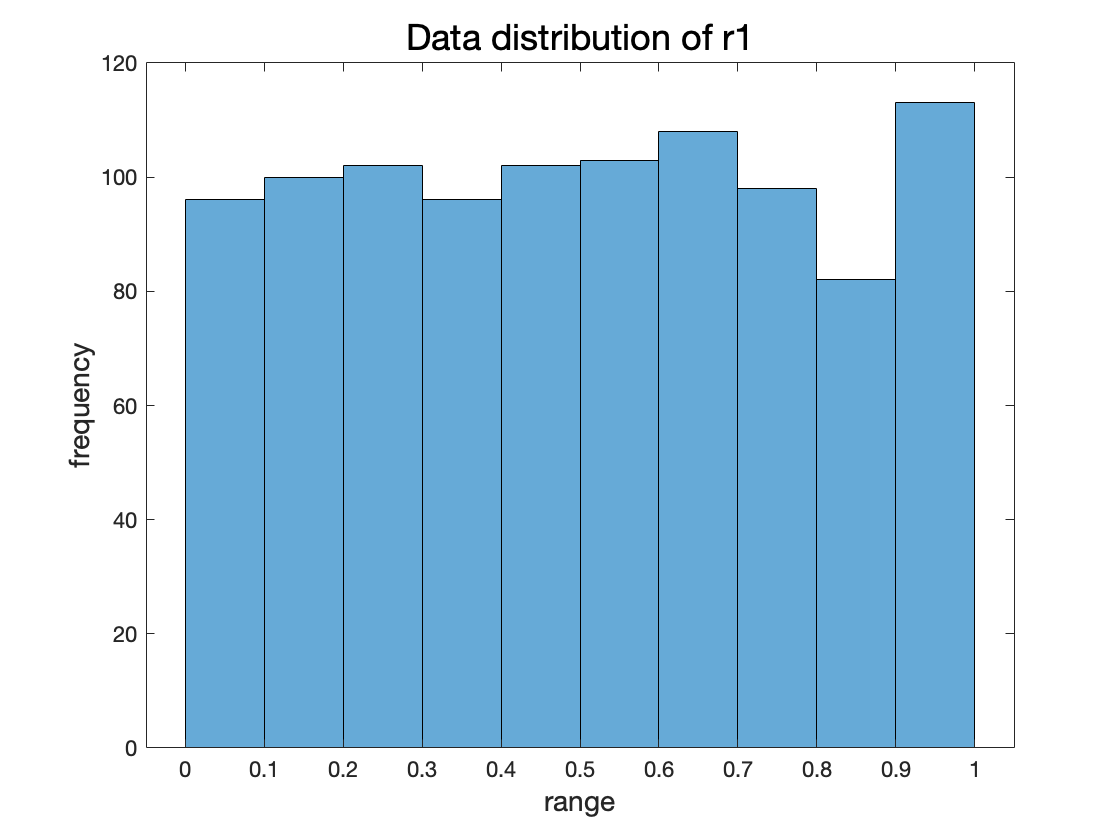

% Generate r1
r1 = rand(1000, 1);
r2 = rand(10000, 1);
r3 = rand(100000, 1);

% Plot a histogram for r1
bins = 10;
histogram(r1, bins)
xlabel('range', 'FontSize', 14)
ylabel('frequency', 'FontSize', 14)
title('Data distribution of r1', 'FontSize', 18)

% Calculate variation in values of the histogram
r1_cnt = histcounts(r1, bins) / 1000

r1_cnt =     0.0960    0.1000    0.1020    0.0960    0.1020    0.1030    0.1080    0.0980    0.0820    0.1130


r1_cnt_var = var(r1_cnt)

r1_cnt_var = 6.7778e-05

从图中可以看出，当生成1000个随机数时数据分布得并不完全均匀.

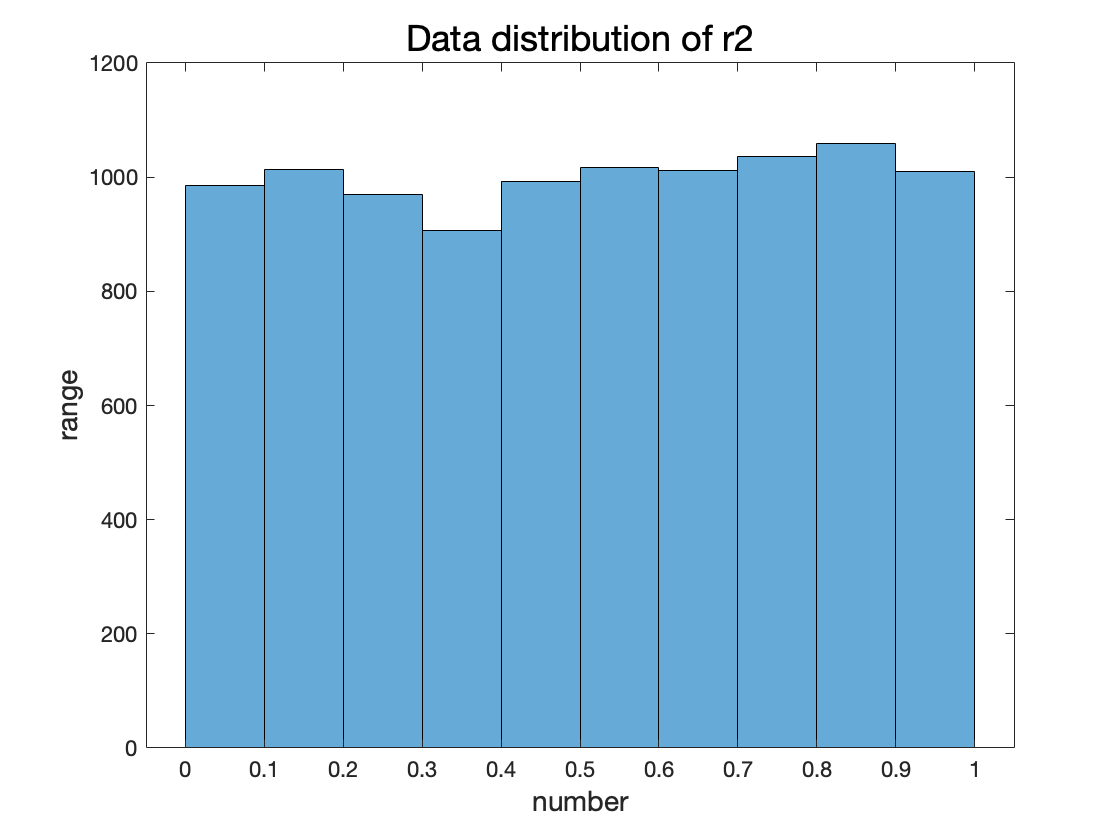

histogram(r2, bins)
xlabel('number', 'FontSize', 14)
ylabel('range', 'FontSize', 14)
title('Data distribution of r2', 'FontSize', 18)

% Calculate variation in values of the histogram
r2_cnt = histcounts(r2, bins) / 10000

r2_cnt =     0.0986    0.1013    0.0969    0.0906    0.0993    0.1017    0.1011    0.1036    0.1059    0.1010


r2_cnt_var = var(r2_cnt)

r2_cnt_var = 1.7220e-05

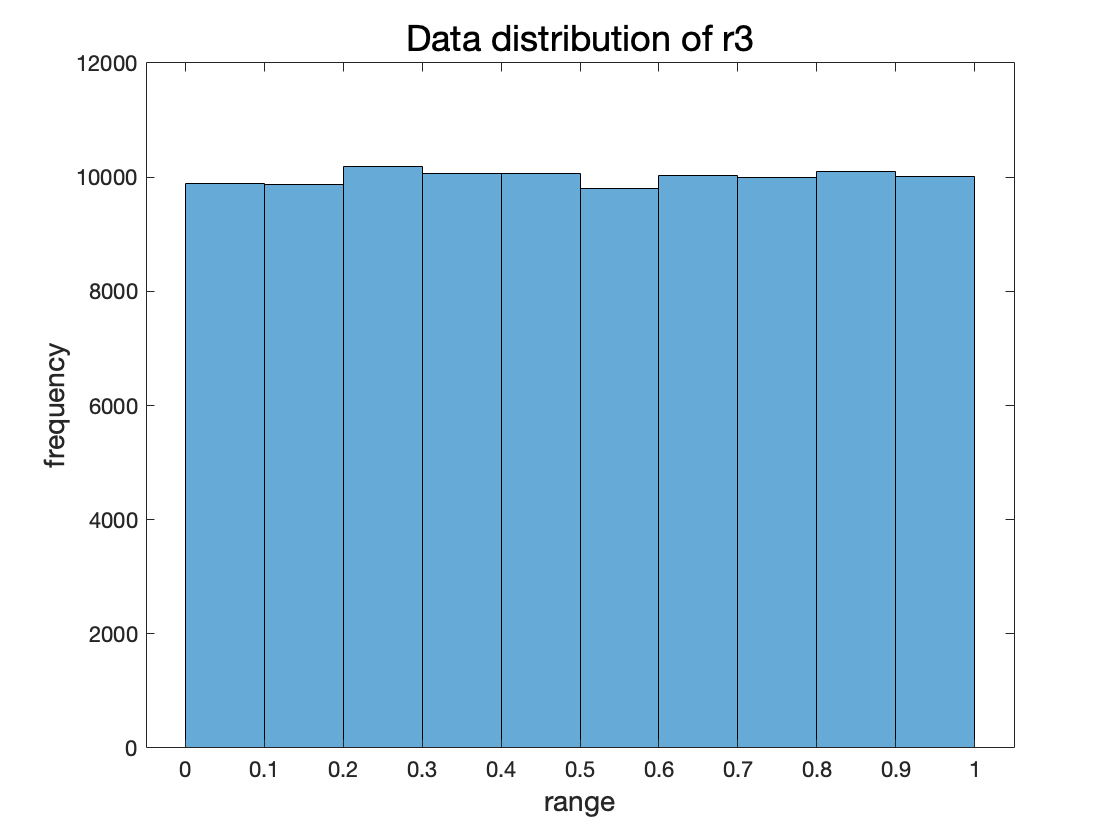


% Plot a histogram for r3
histogram(r3, bins)
xlabel('range', 'FontSize', 14)
ylabel('frequency', 'FontSize', 14)
title('Data distribution of r3', 'FontSize', 18)

% Calculate variation in values of the histogram
r3_cnt = histcounts(r3, bins) / 100000

r3_cnt =     0.0989    0.0987    0.1019    0.1006    0.1006    0.0981    0.1003    0.0999    0.1009    0.1002


r3_cnt_var = var(r3_cnt)

r3_cnt_var = 1.3108e-06

下面验证在每个序列长度多次取样得到的方差的均值与取样大小（序列长度）的平方根大致呈反比例关系，说明增大样本量可以使bins之间的差异减小，即数据分布得更均匀，与根据中心极限定理预测的结果一致.

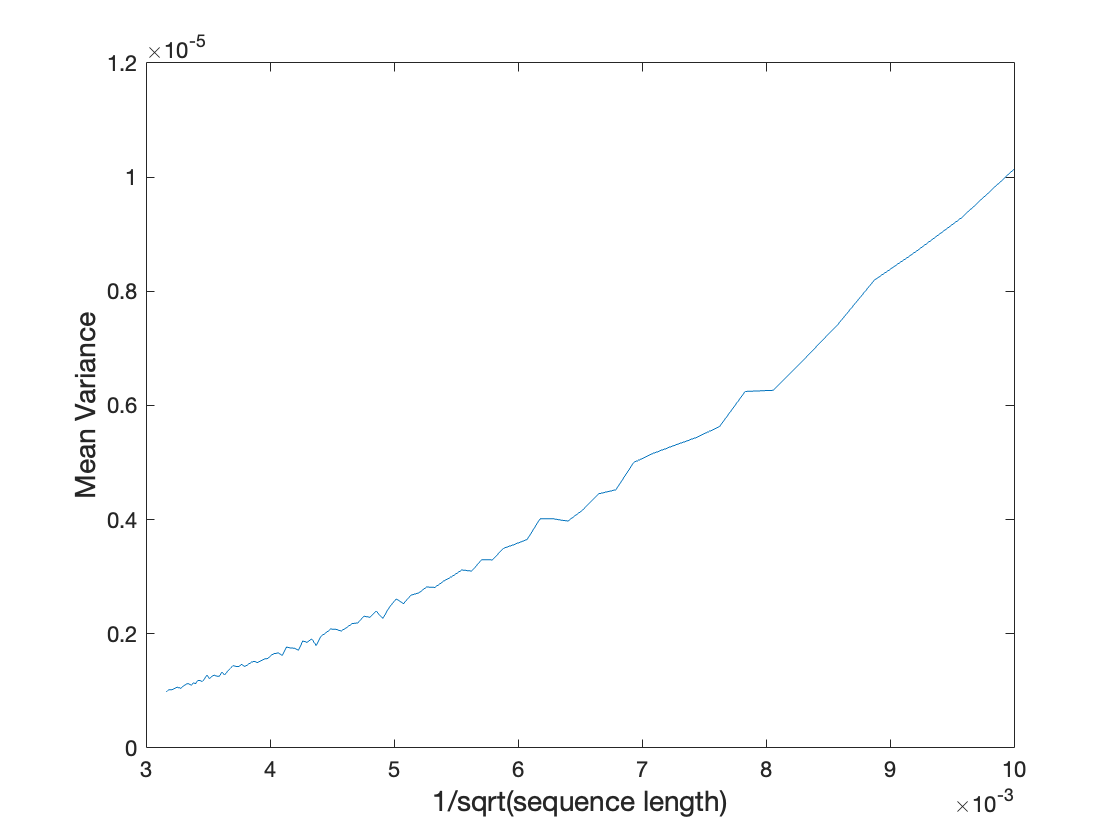

vars_means = zeros(1, 101);
lens = zeros(1, 101);

for i = 1: 101
    len = 900 * i + 9100; % sequence length: [10000, 100000]
    lens(i) = len;
    r_cnt_vars = zeros(1, 50);
    for j = 1: 500 % sampling for 500 times
        r = rand(len, 1);
        r_cnt = histcounts(r, bins) / len;      
        r_cnt_vars(j) = var(r_cnt); % variance
    end
    vars_means(i) = mean(r_cnt_vars); % mean variance
end
plot(sqrt(1./lens), vars_means) % plotting the square root of the inverse of sequence lengths against mean variance
xlabel('1/sqrt(sequence length)', 'FontSize', 14);
ylabel('Mean Variance', 'FontSize', 14);

#### **Exercise 11.2**

Convert the sequence of 1000 random numbers r from the previous exercise into a sequence of outcomes of coin tosses in which **the probability of heads is 0.6** and **the probability of tails is 0.4**. Let **1** represent an outcome of **heads** and let **0 **represent an outcome of **tails**. To generate from r a sequence of 0’s and 1’s that reflect these probabilities, we assign random numbers less than 0.4 to tails, and random numbers larger than 0.6 to heads. 

#### ﻿Matlab Challenge

﻿Write a "vectorized" program to generate the coin tosses without usingthe command for. ﻿(Hint: The logical operator < can act on vectors and matrices as well as scalars.)

% example
r = rand(1000,1);
seq = zeros(1000,1);
for i=1:1000
    if r(i) < 0.6
        seq(i)=1;
    end
end

% vectorized
seq = r < 0.6;

Recall that this coin tossing experiment can be modeled by the **binomial distribution**: the probability of **k heads **in the sequence is given by

﻿Calculate the probability of k heads **for values of k between 500 and 700** **in a sequence of 1000 independent tosses**. Plot your results **with k on the x-axis** and **the probability of k heads on the y-axis**. **Comment** on the shape of the plot.

% binomal distribution plot
k = 500: 700;
p_k = zeros(1, 700 - 500 + 1);
for i = 1: 201
    p_k(i) = nchoosek(1000, i + 499) * 0.6^(i + 499) * 0.4^(1000 - (i + 499));
end

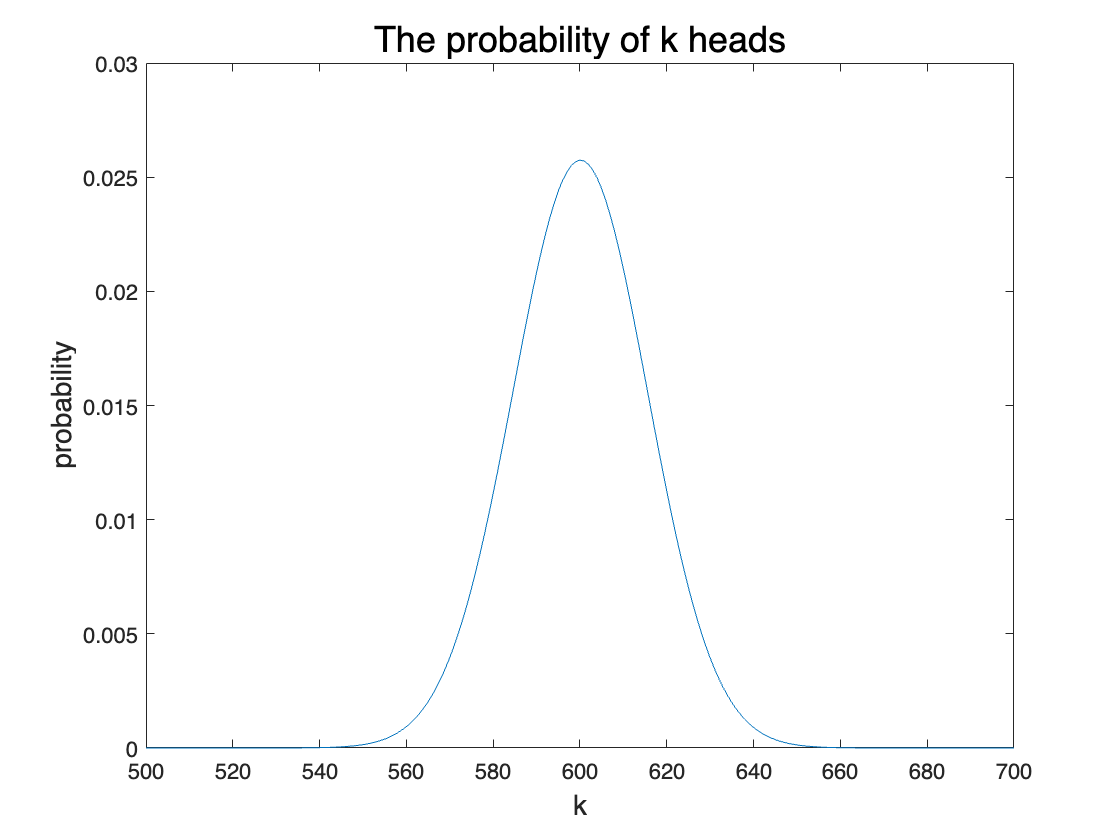

figure;
plot(k, p_k);
title('The probability of k heads', 'FontSize', 18);
xlabel('k', 'FontSize', 14);
ylabel('probability', 'FontSize', 14);

**Comment:** 二项分布曲线呈钟形，在$k=N*H=600$处达到最大值，表明在$N=1000$次抛硬币测试中硬币正面向上出现600次的概率最大（略大于2.5%）。这是因为在我们的设定中，硬币正面朝上的概率为$H=0\ldotp 6$，反面朝上的概率为$T=0\ldotp 4$，该二项分布曲线的积分（累加和）为$1=\sum_{k=0}^{1000} c_k H^k T^{1000-k} ={\left(H+T\right)}^{1000}$。该概率分布还可以看作在**充分多次**试验（每次试验完成1000次抛硬币测试）中，硬币正面向上k次的试验次数的分布（下一小问）.

﻿Now test the binomial distribution by doing **1000 repetitions** of the sequence of **1000 coin tosses **and plot a histogram of the number of heads obtained **in each repetition**. Compare the results with the predictions from the binomial distribution.

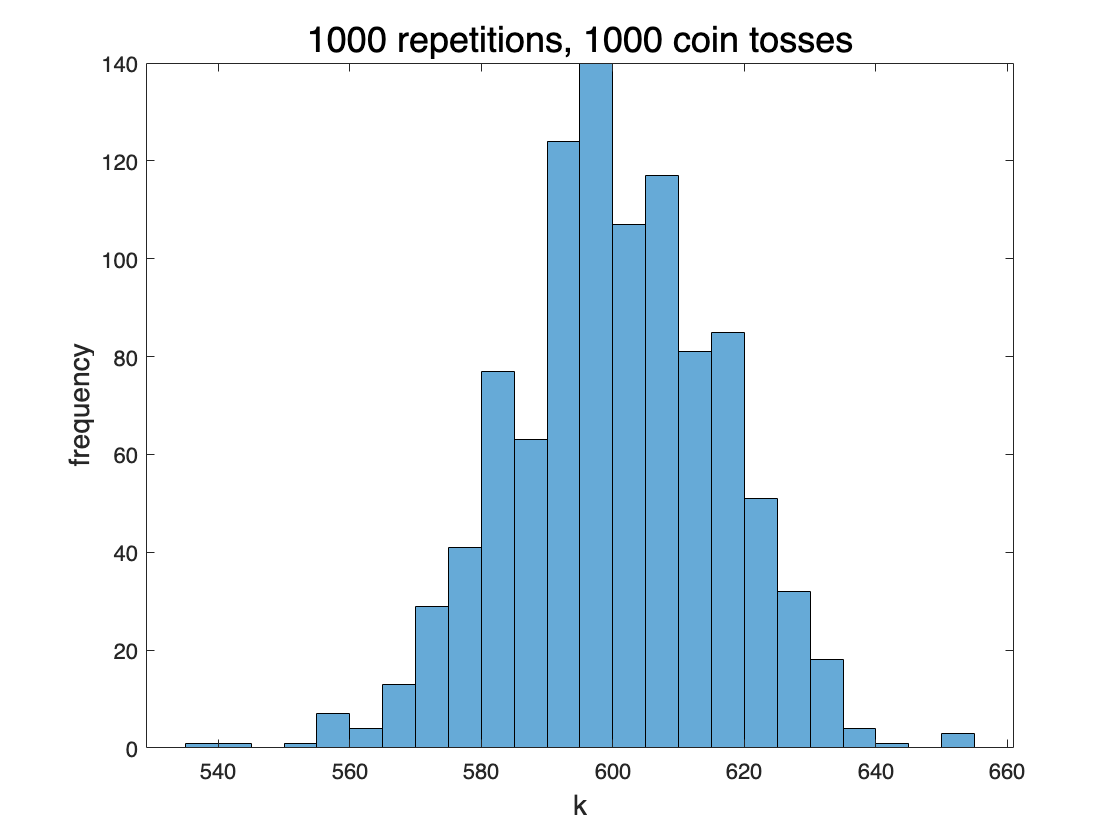

head_cnts = zeros(1, 1000);
for i = 1: 1000 % repeat 1000 times
    r = rand(1000, 1); % 1000 coin tosses (N = 1000)
    result = (r < 0.6);
    head_cnts(i) = sum(result); % count 1's
end

% plot the result
figure;
histogram(head_cnts);
title('1000 repetitions, 1000 coin tosses', 'FontSize', 18);
xlabel('k', 'FontSize', 14);
ylabel('frequency', 'FontSize', 14);

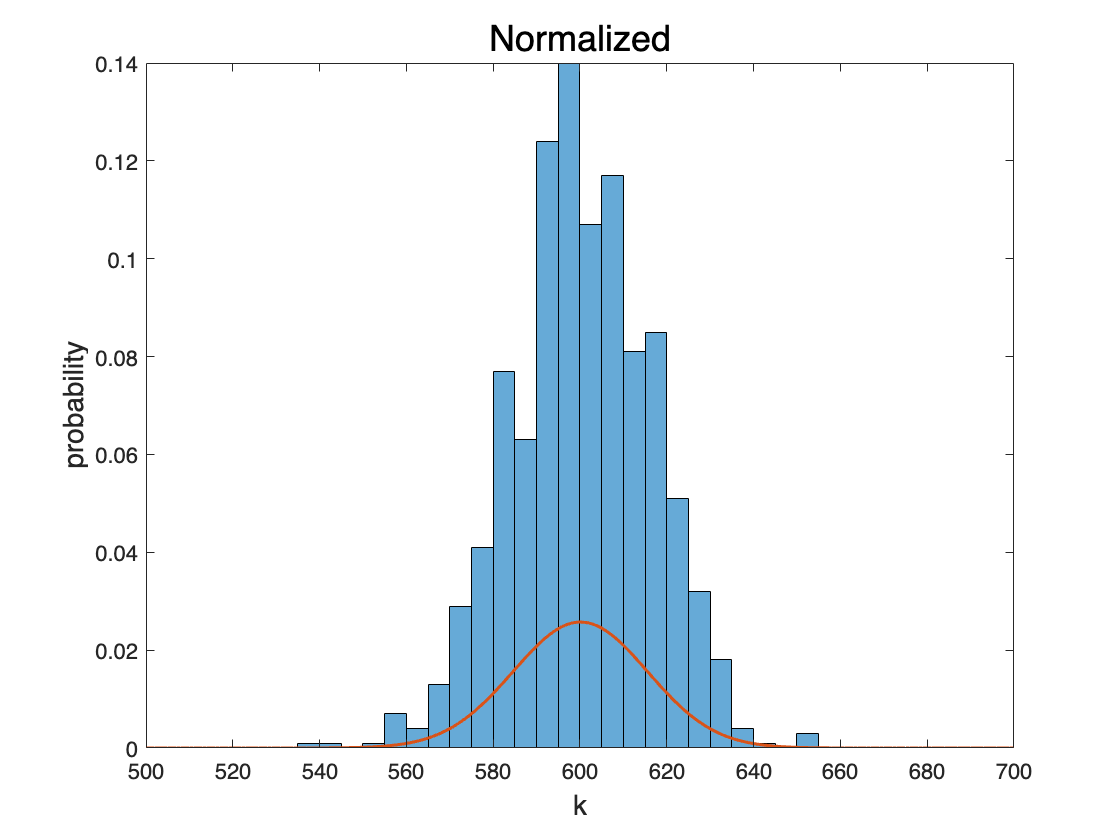

figure;
histogram(head_cnts,'Normalization','probability');
title('Normalized', 'FontSize', 18);
xlabel('k', 'FontSize', 14);
ylabel('probability', 'FontSize', 14);
hold on;
plot(k, p_k, 'LineWidth', 1.5);

结果的分布与二项分布预测的分布在形式上接近，但是数据太过集中于$k=600$附近，导致经过normalization后与二项分布预测的结果差别很大，原因在于试验重复次数（1000次）**不足够大**，从而使通过统计得到的结果分布偏离二项分布较多。

﻿Repeat this experiment with **10000 repetitions** of **100 coin tosses**. **Comment** on the differences you observe between this histogram and the histogram for 1000 repetitions of tosses of 1000 coins.

k = 1: 100;
p_k = zeros(1, 100);
for i = 1: 100
    p_k(i) = nchoosek(100, i) * 0.6^(i) * 0.4^(100 - i);
end

head_cnts = zeros(1, 10000);
for i = 1: 10000 % repeat 10000 times
    r = rand(100, 1); % 100 coin tosses (N = 100)
    result = (r < 0.6);
    head_cnts(i) = sum(result); % count 1's
end
head_cnts

head_cnts =     55    56    58    71    64    59    64    58    60    60    54    67    52    54    62    61    47    58    57    65    59    58    54    51    67    63    64    65    64    69    58    65    63    58    60    51    58    59    56    68    65    61    63    56    65    58    61    58    56    61


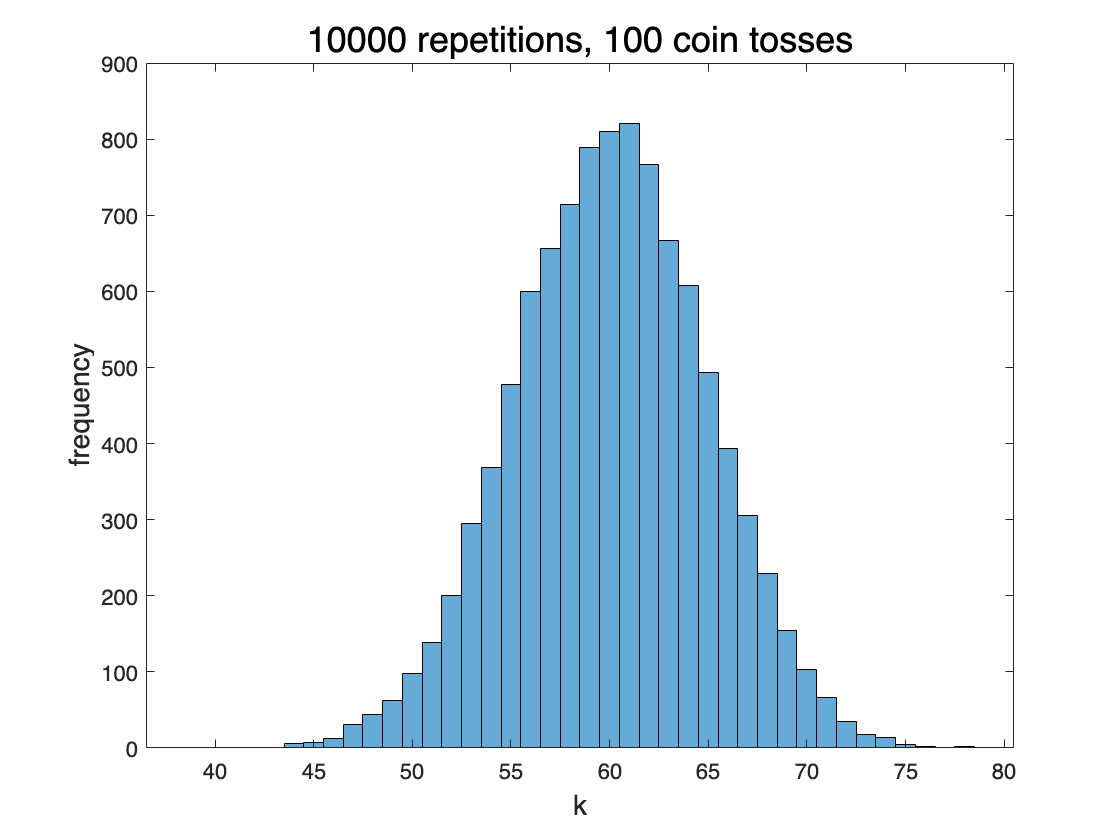

figure;
histogram(head_cnts);
title('10000 repetitions, 100 coin tosses', 'FontSize', 18);
xlabel('k', 'FontSize', 14);
ylabel('frequency', 'FontSize', 14);

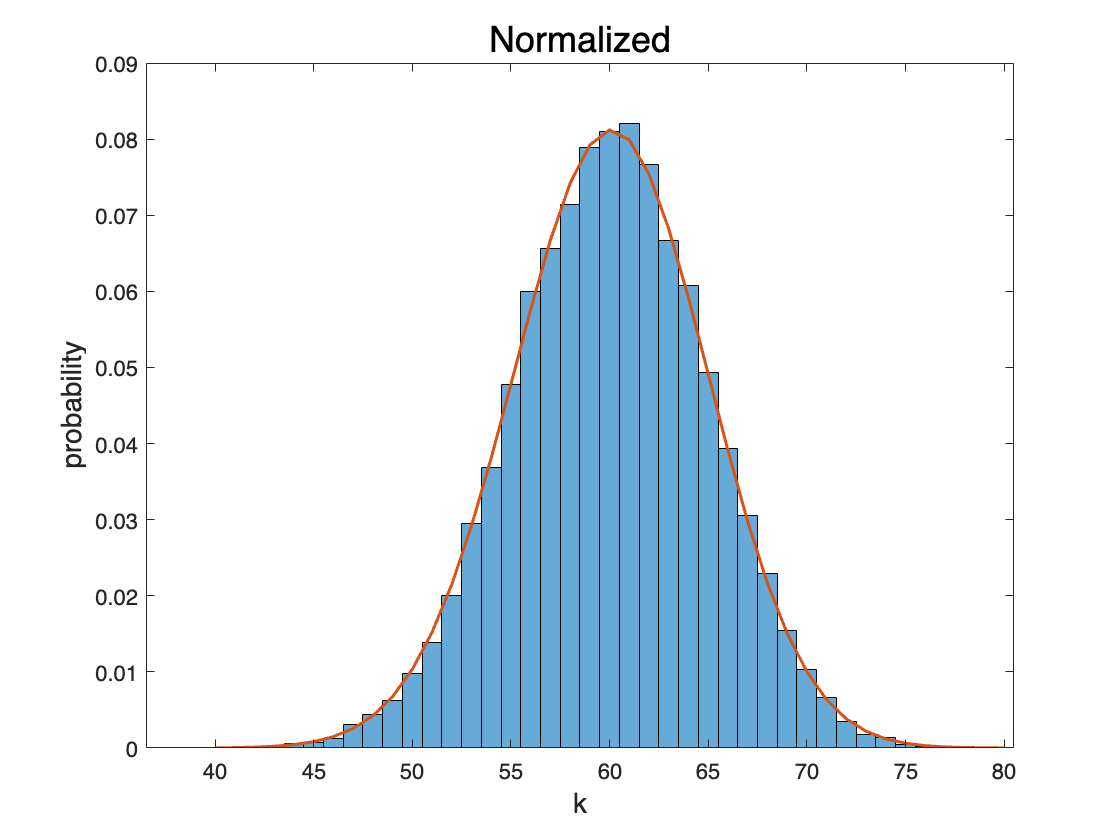

figure;
histogram(head_cnts,'Normalization','probability');
title('Normalized', 'FontSize', 18);
xlabel('k', 'FontSize', 14);
ylabel('probability', 'FontSize', 14);
hold on;
plot(40:80, p_k(40:80), 'LineWidth', 1.5);

**Comment:** 与1000*1000测试相比，10000*100测试得到的结果分布更接近二项分布（数据分布相对更加均匀，而1000*1000测试过于集中在$k_{\max }$附近），尽管两种测试方法总的抛硬币次数相等. 由以上讨论可以得出结论：只有当试验重复次数足够多时，结果才具有统计学意义，才能够得到正确的近似二项分布的试验结果.

### EG Exercise

#### ﻿**Exercise ﻿3.5**

The histogram of expected **residence times** for each state in a Markov chain is **exponential**, with **different exponentials for different states**. To observe this in the simplest case, use a random number generator to produce data for **a two-state Markov chain**. Next, determine the **transitions** that occur in these data as the state changes, and **the residence times between** these. Finally, compute** histograms** of the residence times.

% p1 = rand(1,1);
% p2 = rand(1,1);
% m = [p1, p2
%     1 - p1, 1 - p2];
m = [0.4 0.7
     0.6 0.3]; % the "simplelest case" in the book
% use a random number generator to make a two-state Markov chain
tmax = 1000;
r = rand(1, tmax);
state_t = zeros(1, tmax);
state_t(1) = 1; % start from state 1, another state is state 2
cur_state = 1;
for t = 2: tmax
    if r(t) < m(1, cur_state)
        cur_state = 1;
    else
        cur_state = 2;
    end
    state_t(t) = cur_state;
end
state_t

state_t =      1     2     1     2     1     1     1     2     2     2     1     2     2     1     2     1     2     2     2     2     1     1     2     2     1     2     2     1     2     1     2     1     1     1     1     2     1     1     2     1     2     1     2     2     1     2     1     2     2     2


% determine the transitions and the residence times
cur_state = 1;
changes = [];
change_cnt = 1;
for t = 2: tmax
    if state_t(t) ~= cur_state
        if cur_state == 1
            cur_state = 2;
        else
            cur_state = 1;
        end
        changes(change_cnt) = t;
        change_cnt = change_cnt + 1;
    end
end
changes

changes =      2     3     4     5     8    11    12    14    15    16    17    21    23    25    26    28    29    30    31    32    36    37    39    40    41    42    43    45    46    47    48    51    52    53    56    58    59    60    61    62    63    64    65    67    71    72    73    74    75    76


state1_resident_record = [];
record1_cnt = 1;
state2_resident_record = [];
record2_cnt = 1;
cur_t = 1;
cur_state = 1;
for i = 1: length(changes)
    if cur_state == 1
        state1_resident_record(record1_cnt) = changes(i) - cur_t;
        cur_state = 2;
        record1_cnt = record1_cnt + 1;
    else
        state2_resident_record(record2_cnt) = changes(i) - cur_t;
        cur_state = 1;
        record2_cnt = record2_cnt + 1;
    end
    cur_t = changes(i);
end
state1_resident_record

state1_resident_record =      1     1     3     1     1     1     2     1     1     1     4     2     1     1     1     1     1     3     1     1     1     1     4     1     1     3     2     1     1     1     2     1     4     1     1     1     1     3     1     1     1     1     1     3     1     4     1     1     2     6


state2_resident_record

state2_resident_record =      1     1     3     2     1     4     2     2     1     1     1     1     1     2     1     3     1     2     1     1     1     2     1     1     1     1     1     2     2     1     3     1     1     1     1     1     1     1     1     1     1     1     3     1     1     1     1     1     1     1


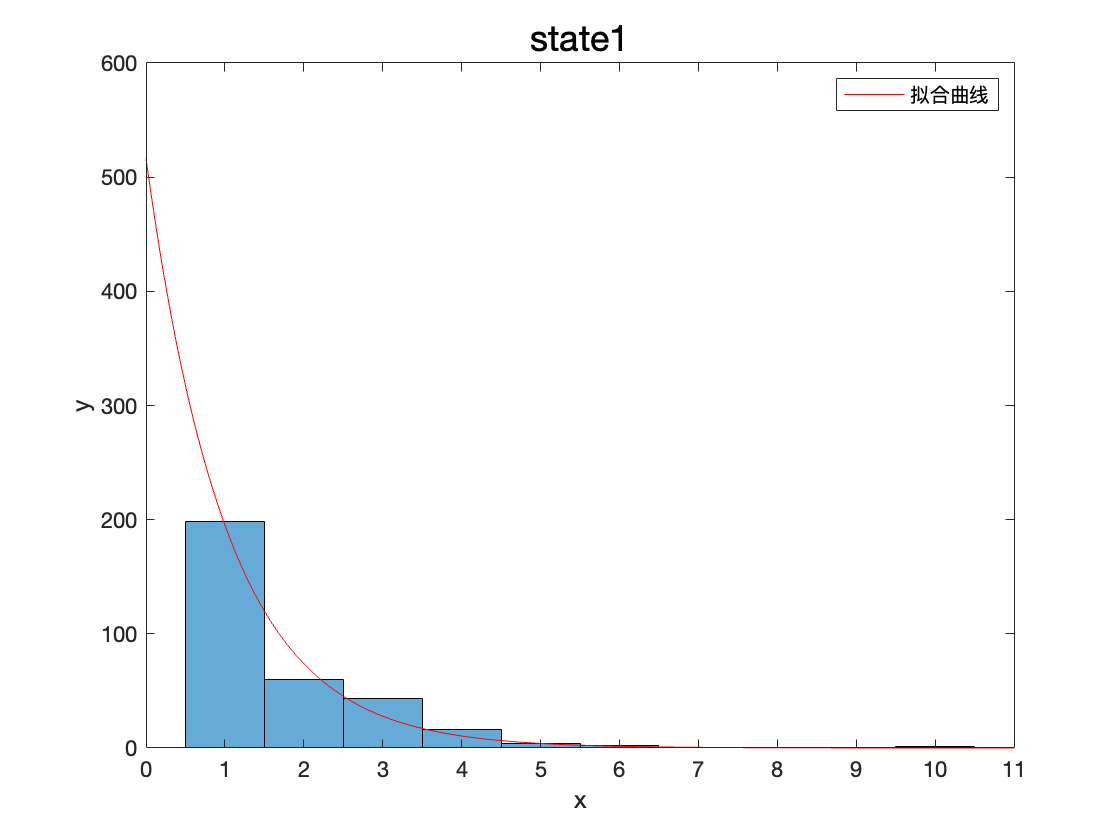

% compute histograms of the residence times
figure;
histogram(state1_resident_record)
xlabel('resident time','FontSize',14);
ylabel('frequency','FontSize',14);
title('state1','FontSize',18);
hold on;
hist1 = histcounts(state1_resident_record);
fit1 = fit((1:length(hist1))', (hist1)' , 'exp1');
plot(fit1);

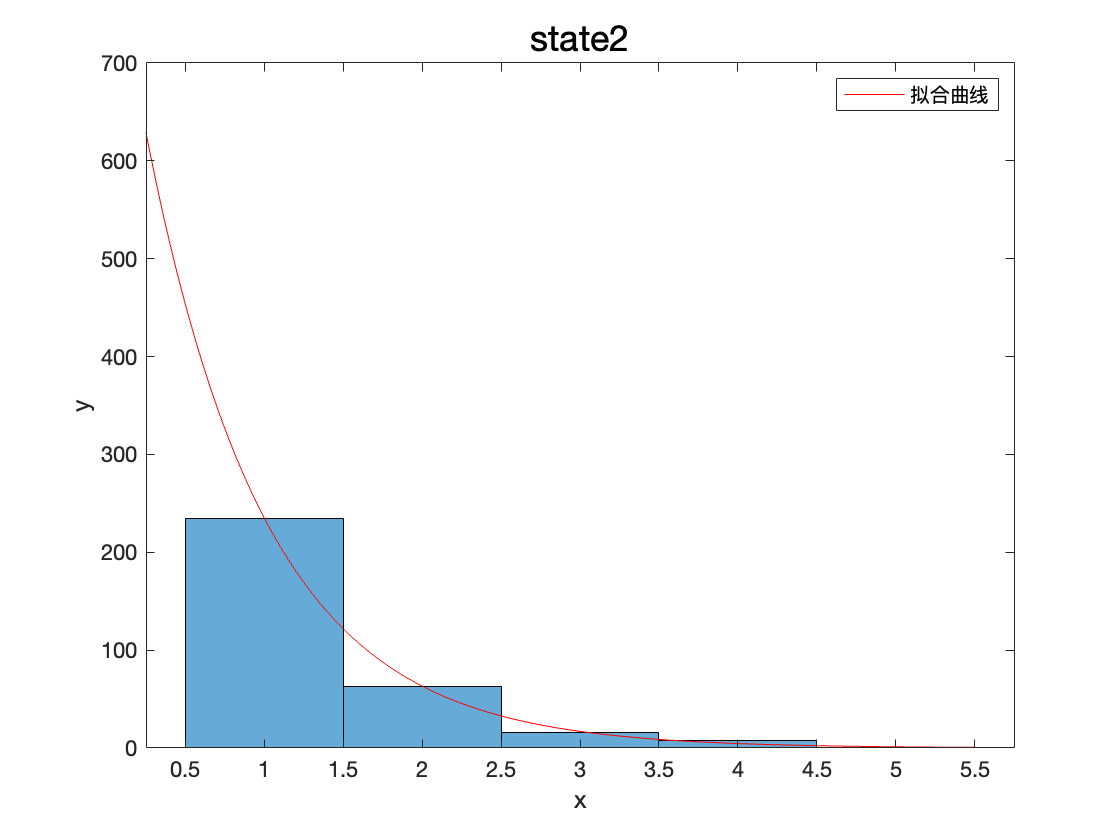

figure
histogram(state2_resident_record)
xlabel('resident time','FontSize',14);
ylabel('frequency','FontSize',14);
title('state2','FontSize',18);
hold on;
hist2 = histcounts(state2_resident_record);
fit2 = fit((1:length(hist2))', (hist2)' , 'exp1');
plot(fit2);

#### Exercise 3.6

This exercise examines Markov chains with **three states**: one “open” state O and two “closed” states C1 and C2. We assume that **measurements do not distinguish** between the states C1 and C2, but we want to demonstrate that there are more than two states.

(a) Generate a set of **1,000,000 samples** from the Markov chain with transition matrix

 You can see from this matrix that the probability 0.7 of staying in state C2 is **much smaller** than the probability 0.98 of staying in state C1 or the probability 0.95 of remaining in state O.

A = [0.98 0.1 0
     0.02 0.7 0.05
        0 0.2 0.95];
tmax = 1000000;
r = rand(1, tmax);
state_t = zeros(1, tmax);
state_t(1) = 1; % start from C1
cur_state = 1;
for t = 2: tmax
    if r(t) < A(1, cur_state)
        cur_state = 1;
    elseif r(t) < A(1, cur_state) + A(2, cur_state)
            cur_state = 2;
    else
            cur_state = 3;
    end
    state_t(t) = cur_state;
end
state_t

state_t =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


(b) Compute the eigenvalues and eigenvectors of the matrix A. Compute the total time that your sample data in the vector states spends in each state and compare the results with predictions          coming from the dominant right eigenvector of A.

% eigenvalues and eigenvectors of A
[V,D] = eig(A);
L = diag(D);
V, D, L

V =    -0.2488   -0.7391    0.7715
    0.7979    0.0692    0.1543
   -0.5490    0.6700    0.6172


D =     0.6594         0         0
         0    0.9706         0
         0         0    1.0000


L =     0.6594
    0.9706
    1.0000


% Compute the total time in each state
total = zeros(3,1);
total(1) = length(find(state_t == 1));
total(2) = length(find(state_t == 2));
total(3) = length(find(state_t == 3));
total 

total =       504686
      100251
      395063


% Compute the prediction time in each state
predict_time = (V(:, 3) / sum(V(:, 3))) * tmax

predict_time = 1.0e+05 *

    5.0000
    1.0000
    4.0000


(c) Produce a new vector rstates by “reducing” the data in the vector states so that states 1 and 2 are indistinguishable. The states of rstates will be called “closed” and “open.”

% C1, C2 -> state 1
% O -> state 2
rstates = (state_t == 3) + 1

rstates =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


(d) Plot histograms of the residence times of the open and closed states **in rstates**.

% determine the transitions and the residence times
cur_state = 1; % start from C1
changes = [];
change_cnt = 1;
for t = 2: tmax
    if rstates(t) ~= cur_state
        cur_state = rstates(t);
        changes(change_cnt) = t;
        change_cnt = change_cnt + 1;
    end
end
changes

changes =          341         361         363         396         582         609         610         635         637         643         686         692         693         699         700         746         747         758         915         932         936         960         961         971         972        1009        1014        1026        1071        1103        1104        1107        1118        1128        1136        1178        1255        1271        1274        1285        1290        1347        1352        1373        1746        1759        1760        1792        1793        1833


state1_resident_record = [];
record1_cnt = 1;
state2_resident_record = [];
record2_cnt = 1;
cur_t = 1;
cur_state = 1;
for i = 1: length(changes)
    if cur_state == 1
        state1_resident_record(record1_cnt) = changes(i) - cur_t;
        cur_state = 2;
        record1_cnt = record1_cnt + 1;
    else
        state2_resident_record(record2_cnt) = changes(i) - cur_t;
        cur_state = 1;
        record2_cnt = record2_cnt + 1;
    end
    cur_t = changes(i);
end
state1_resident_record

state1_resident_record =    340     2   186     1     2    43     1     1     1   157     4     1     1     5    45     1    11     8    77     3     5     5   373     1     1     1    40     4     2     1    36    73     3   434   126    15     1    49     2     2    25     4    82     5     1     2    23     1     1    96


state2_resident_record

state2_resident_record =     20    33    27    25     6     6     6    46    11    17    24    10    37    12    32     3    10    42    16    11    57    21    13    32    40     2     3     9    31     2    10    70     7     2    10    46    18     1    10    31    57    53     1    15    13     2    10    13    14    85


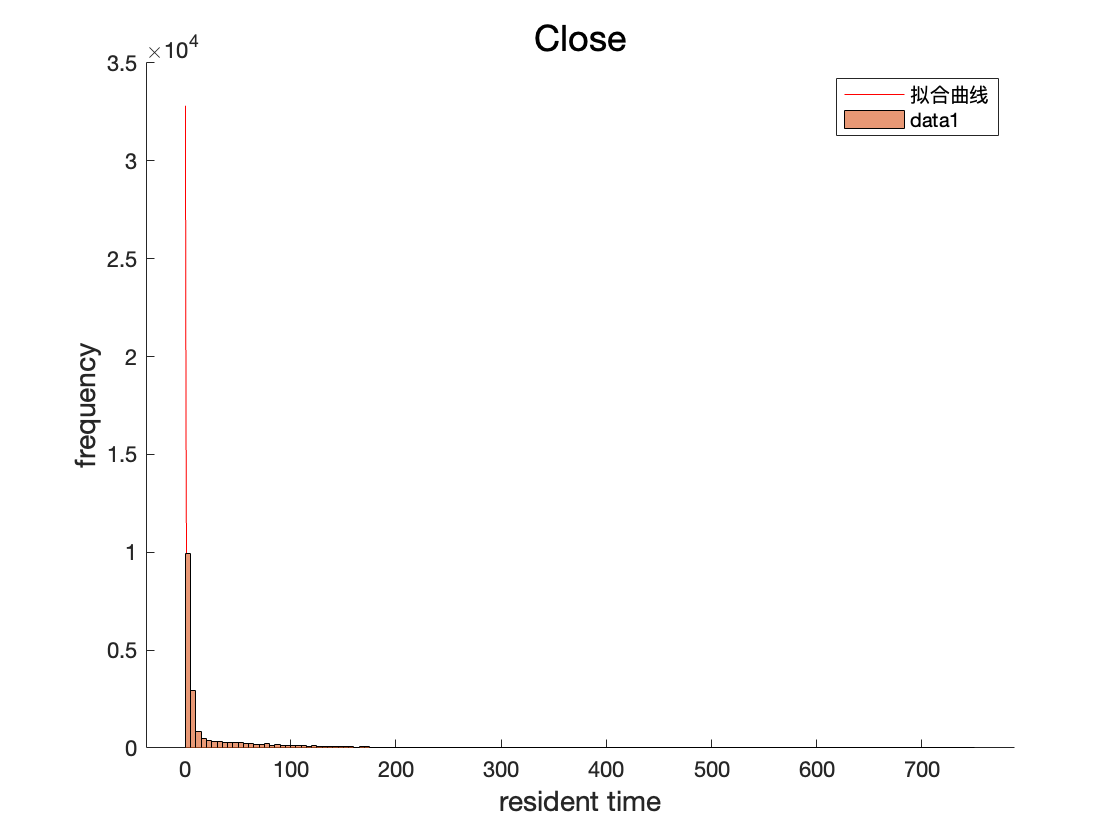

% Compute histograms of the residence times
figure;
hold on
hist1 = histcounts(state1_resident_record);
fit_1 = fit((1:length(hist1))', (hist1)' , 'exp1');
plot(fit_1);
histogram(state1_resident_record)
xlabel('resident time','FontSize',14);
ylabel('frequency','FontSize',14);
title('Close','FontSize',18);

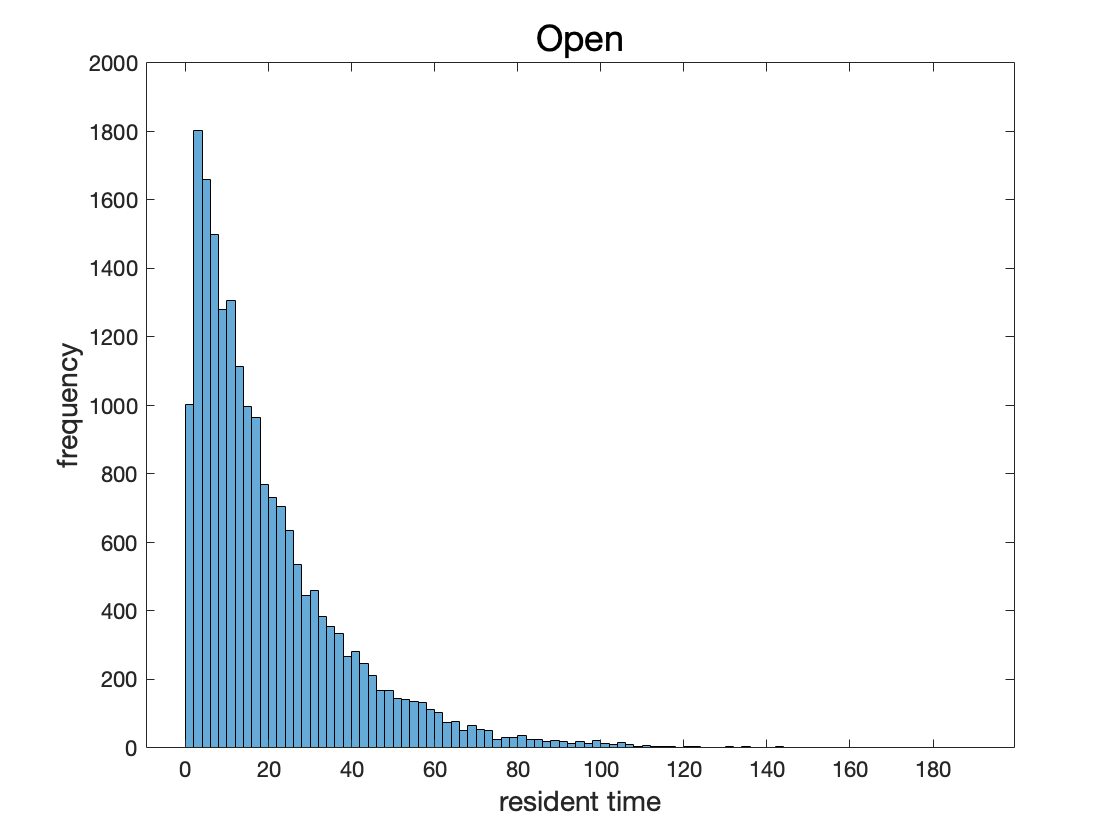

figure
histogram(state2_resident_record)
xlabel('resident time','FontSize',14);
ylabel('frequency','FontSize',14);
title('Open','FontSize',18);

(e) Comment on the shapes of the distributions for open and closed states. Show that the residence time distribution of** the closed states is not fitted** well by an exponential distribution. Using your knowledge of the transition matrix A, make a prediction about what the residence time distributions of the open states should be.

**Comment: **如上图所示，Close状态的resident time大部分情况下均很小，数据大量集中在数值较小的区间，用指数分布的拟合效果不佳。根据矩阵A的特征以及分布图，可以推测Open状态的resident time频率分布大致符合指数分布。﻿